clearvars;

Data construction

N = 5000; % Number of points
t = linspace(0,5,N)'; % Time vector with fs = 500 Hz

a= 0.75;
phi = 0;
snr = 10;

s = sawtooth(2*pi*2*t(1:N,1),0.5); % Sawtooth signal
n1 = 0.2*sin(2*pi*50*t(1:N/2,1)-phi); % Sinusoid at 50 Hz
n2 = 0.3*sin(2* pi*100*t(N/2+1:N,1)-phi); % Sinusoid at 100 Hz
nwg = s - awgn(s,snr,'measured'); % Gaussian white noise

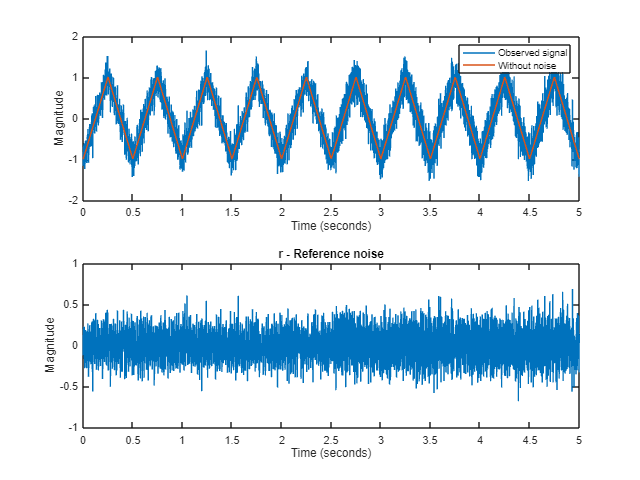

r = (nwg + [n1 ;n2])*a;
x = s+nwg + [n1 ;n2];

figure('Position', [100, 100, 800, 600]);
subplot(2, 1, 1); 
plot(t, x);
hold on;
plot(t, s);
legend("Observed signal","Without noise");
xlabel("Time (seconds)");
ylabel("Magnitude");

subplot(2, 1, 2); 
plot(t, r);
xlabel("Time (seconds)");
ylabel("Magnitude");
title("r - Reference noise");

power_x = sum(abs(x).^2) / length(x); %power of x
M = 20;
lambda_max = 20*M*power_x;   

error_matrix = zeros(length(3:20),length(0.001:0.0005:2/lambda_max));
k=0;

best_M = 0;
best_constructed_signal = [];
min_error = inf;


for M = 3:20
    w = rand(M,1);
    k = k + 1;
    j = 0;
    for miu = 0.001:0.0005:0.0423
        j = j+1;
        constructed_signal = [];
        for i=1:length(x)-M+1
            R = r(i:i+M-1);
            y = w'*R;
            e = x(i+M-1)-y;
            constructed_signal = [constructed_signal; e];
            w = w + 2*miu*e*R;
        end
        error = sum((s(M:end) - constructed_signal).^2);
        error_matrix(k,j) = error;

        if error < min_error
            min_error = error;
            best_constructed_signal = constructed_signal;
            best_M = M;
        end
    end
end

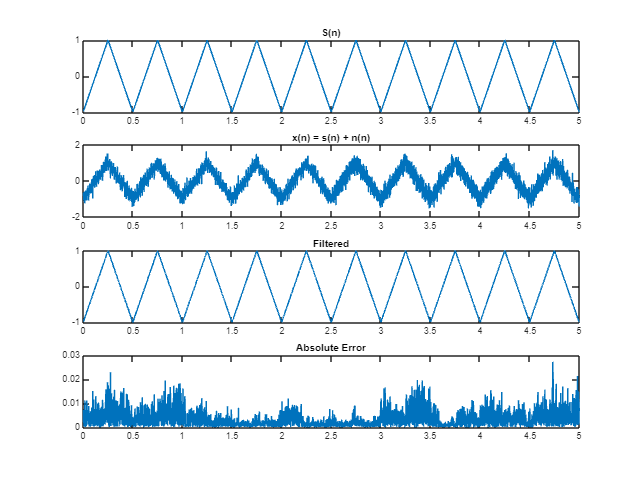

figure('Position', [100, 100, 800, 600]);
subplot(4, 1, 1); 
plot(t(best_M:end), s(best_M:end));
title("S(n)")

subplot(4, 1, 2); 
plot(t(best_M:end), x(best_M:end));
title("x(n) = s(n) + n(n)");

subplot(4, 1, 3); 
plot(t(best_M:end),best_constructed_signal);
title("Filtered");

subplot(4, 1, 4); 
plot(t(best_M:end), abs(s(best_M:end)-best_constructed_signal));
title("Absolute Error");

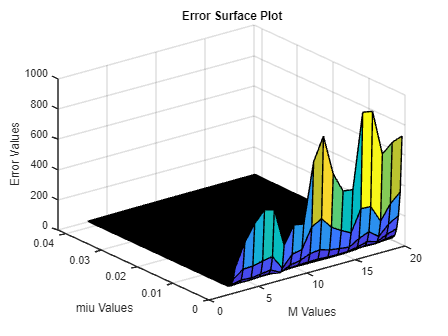


M_values = 3:20;
miu_values = 0.001:0.0005:0.0423;

figure;
[M, Miu] = meshgrid(M_values, miu_values);
surf(M, Miu, error_matrix');

xlabel('M Values');
ylabel('miu Values');
zlabel('Error Values');
title('Error Surface Plot');
view(3);

delta = 1e-3;
lambdas = linspace(0.001,1,100);
error_matrix_RLS = zeros(length(3:25),100);

best_M_RLS= 0;
best_constructed_signal_RLS = [];
best_lambda = 0;
min_error = inf;

k = 0;
for M=3:25
    w_n = rand(M,1);
    k = k+1;
    for i = 1:100
        lambda = lambdas(i);
        constructed_signal = [];
        p_n = (1/delta).*eye(M);
        
        for h = 1:length(x)-M+1
            R = r(i:i+M-1);
            k_n = (lambda^(-1)*(p_n*R)) / (1+lambda^(-1)*((R'*p_n)*R));
            p_n = (lambda^(-1)*p_n) - (lambda^(-1)*((k_n*R')*p_n));

            alpha_n = x(i+M-1) - w_n'*R;
            w_n = w_n+k_n.*alpha_n;
            constructed_signal = [constructed_signal; alpha_n];

            
        end

        error = sum((s(M:end) - constructed_signal).^2);
        error_matrix_RLS(k,i) = error;

        if error < min_error
            best_M_RLS = M;
            best_lambda = lambda;
            min_error = error;
            best_constructed_signal_RLS = constructed_signal;
        end
    end
end

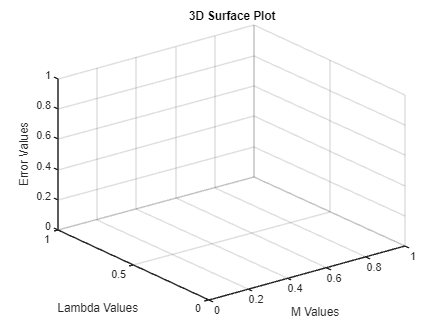

figure;
M_values = 3:25;
[M, Lamda] = meshgrid(M_values, lambdas);
surf(M, Lamda, error_matrix_RLS');

xlabel('M Values');
ylabel('Lambda Values');
zlabel('Error Values');
title('3D Surface Plot');
view(3);

figure;
plot(best_constructed_signal_RLS)
